# Catamaran Identification

loadBag
getUSV

SampleTime = mean(diff(USV.time));
PIDSampleTime = 0.1;


## 1. Model of the Catamaran

Catamaran vehicle has been modeled by two decoupled dynamics:

- **Longitudinal dynamic**


$$\begin{array}{l}
v_{\textrm{SS}} =f_v \left(u_v \right)\\
v=G_{v\;} \left(s\right)v_{\textrm{SS}} 
\end{array}$$


- **Yaw rate dynamic**


$$\begin{array}{l}
\omega {\;}_{\textrm{SS}} =f_{\omega } \left(u_{\omega } \right)\\
\omega =G_{\omega } \left(s\right)\omega_{\textrm{SS}} 
\end{array}$$


In the previous formulas:

-  $f_{v\;}$ and $f_{\omega }$ are non-linear functions that map a control action to a steady state speed value

- $G_v \left(s\right)$ and $G_{\omega } \left(s\right)$ are first order transfer function with unity static gain: $G_{v/\omega } \left(s\right)=\frac{1}{1+\tau_{v/\omega } \;s}$

## 2. Open loop Test for Longitudinal Dynamic Identification

With the aim to identificate logitudinal dynamic, catamaran has been controlled with several constant speed commands.

Every command level has been kept until vehicle has reached a steady state speed value.

4 breakpoints has been evaluated avaraging along periods of time purged of transients.

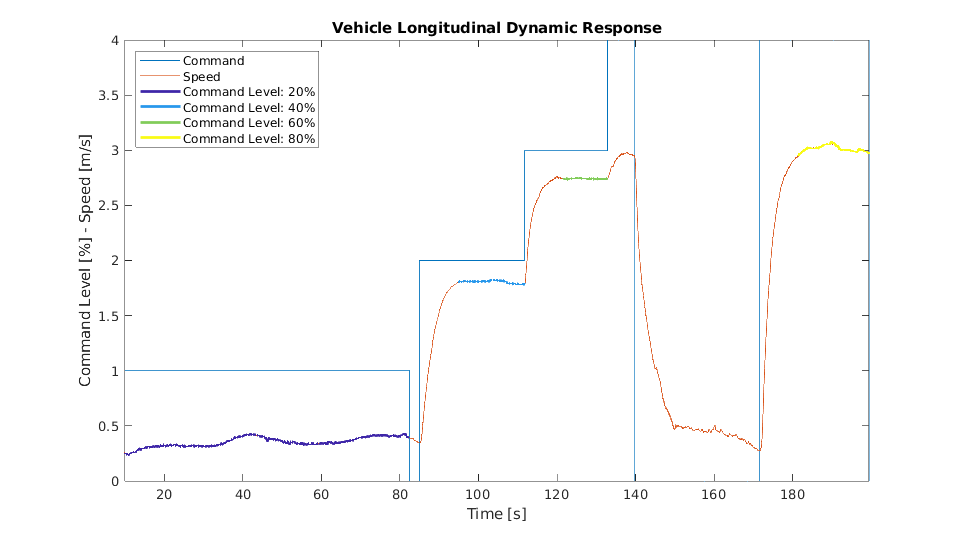

%% Longitudinal Feed Forward Table
speedCommandDelay = 10;                         % SET ME!!!
speedCommandLevelSteps = [20 40 60 80];         % SET ME!!!
speedStep = 0.05;                               % SET ME!!!
% maxSpeed = 3.1;                                 % Optional

if not(exist('maxSpeed', 'var'))
    maxSpeed = max(USV.longSpeed.Data);
end

commandTol = 0.5;
deltaTimeTol = SampleTime*1.05;
speedLevelSteps = cell(size(speedCommandLevelSteps));
speedLevelStepsWeight = cell(size(speedCommandLevelSteps));

fig1 = figure();
fig1.Position = [100 100 960 540];
box on
hold on
plot(USV.speedCmd/20);
plot(USV.longSpeed);
title('Vehicle Longitudinal Dynamic Response');
xlabel('Time [s]');
ylabel('Command Level [%] - Speed [m/s]');
legendFields = {'Command','Speed'};
xlimLowLong = inf;
xlimHighLong = -inf;
colorMap = parula(length(speedCommandLevelSteps));
for commandLevel = speedCommandLevelSteps
    usefulRange = abs(squeeze(USV.speedCmd.Data)-commandLevel) < commandTol & ...
                  abs(squeeze(USV.yawRateCmd.Data)) < commandTol;

    startUsefulPeriod = [diff(USV.time(usefulRange)).'; inf] < deltaTimeTol;
    startUsefulPeriod = startUsefulPeriod & [true; not(startUsefulPeriod(1:end-1))];
    startUsefulPeriodIndex = find(startUsefulPeriod);
    stopUsefulPeriodIndex = [startUsefulPeriodIndex(2:end)-1; length(startUsefulPeriod)];

    usefulSpeedRange = squeeze(USV.longSpeed.Data(usefulRange));
    usefulTimeRange = USV.time(usefulRange);
    for i = 1:length(startUsefulPeriodIndex)
        usefulSpeedPeriod = usefulSpeedRange(startUsefulPeriodIndex(i):stopUsefulPeriodIndex(i));
        usefulTimePeriod = usefulTimeRange(startUsefulPeriodIndex(i):stopUsefulPeriodIndex(i));
        usefulSpeedPeriod = usefulSpeedPeriod(ceil(speedCommandDelay/SampleTime):end);
        usefulTimePeriod = usefulTimePeriod(ceil(speedCommandDelay/SampleTime):end);
        
        if not(isempty(usefulTimePeriod))       
            plot(usefulTimePeriod, usefulSpeedPeriod,'LineWidth', 2, 'color', colorMap(speedCommandLevelSteps == commandLevel,:));
            speedLevelSteps{speedCommandLevelSteps == commandLevel} = [speedLevelSteps{speedCommandLevelSteps == commandLevel} ...
                                                                       mean(usefulSpeedPeriod)];
            speedLevelStepsWeight{speedCommandLevelSteps == commandLevel} = [speedLevelStepsWeight{speedCommandLevelSteps == commandLevel} ...
                                                                             length(usefulTimePeriod)];
            legendFields{1+length(legendFields)} = [ 'Command Level: ' num2str(commandLevel) '%'];
            xlimLowLong = min(xlimLowLong, usefulTimePeriod(1));
            xlimHighLong = max(xlimHighLong, usefulTimePeriod(end));
        end
    end
    
end
clear commandLevel colorMap usefulRange startUsefulPeriod startUsefulPeriodIndex stopUsefulPeriodIndex
clear usefulSpeedRange usefulTimeRange i usefulSpeedPeriod usefulTimePeriod

legend(legendFields, 'Location', 'northwest');
xlim([xlimLowLong xlimHighLong]);
orient(fig1,'landscape')
print(fig1,'2.LongitudinalIdentification.pdf','-dpdf')


speedMeanLevelSteps = zeros(size(speedCommandLevelSteps));
for commandLevel = speedCommandLevelSteps
    for i = 1:length(speedLevelSteps{commandLevel == speedCommandLevelSteps})
        speedMeanLevelSteps(commandLevel == speedCommandLevelSteps) = ...
            sum(speedLevelSteps{commandLevel == speedCommandLevelSteps}.*...
                speedLevelStepsWeight{commandLevel == speedCommandLevelSteps}./...
                sum(speedLevelStepsWeight{commandLevel == speedCommandLevelSteps}));
    end
end
for commandLevel = speedCommandLevelSteps
    if commandLevel ~= speedCommandLevelSteps(1)
        disp('______________________________________________')
    end
    disp(['Command Level: ' num2str(commandLevel) '% | ' ...
          'Steady Speed: ' num2str(speedMeanLevelSteps(commandLevel == speedCommandLevelSteps)) 'm/s']);
end

Command Level: 20% | Steady Speed: 0.35387m/s


______________________________________________


Command Level: 40% | Steady Speed: 1.8059m/s


______________________________________________


Command Level: 60% | Steady Speed: 2.7417m/s


______________________________________________


Command Level: 80% | Steady Speed: 3.0145m/s


clear commandLevel i

### 2.1 Longitudinal steady-state function

Non-linear function $f_v \left(u_v \right)$ can be obtained by interpolating the breakpoint values.

$f_v \left(0\right)=0$ and $f_v \left(u_{v\;\textrm{MAX}} \right)=v_{\textrm{MAX}}$ are assumed to be 2 more breakpoints.

if 1
%disp('______________________________________________');
disp('Command Level: 0%  | Steady Speed: 0m/s');
disp('______________________________________________');
disp(['Command Level: 100%| Steady Speed: ' num2str(maxSpeed) 'm/s']);
end

Command Level: 0%  | Steady Speed: 0m/s


______________________________________________


Command Level: 100%| Steady Speed: 3.0771m/s


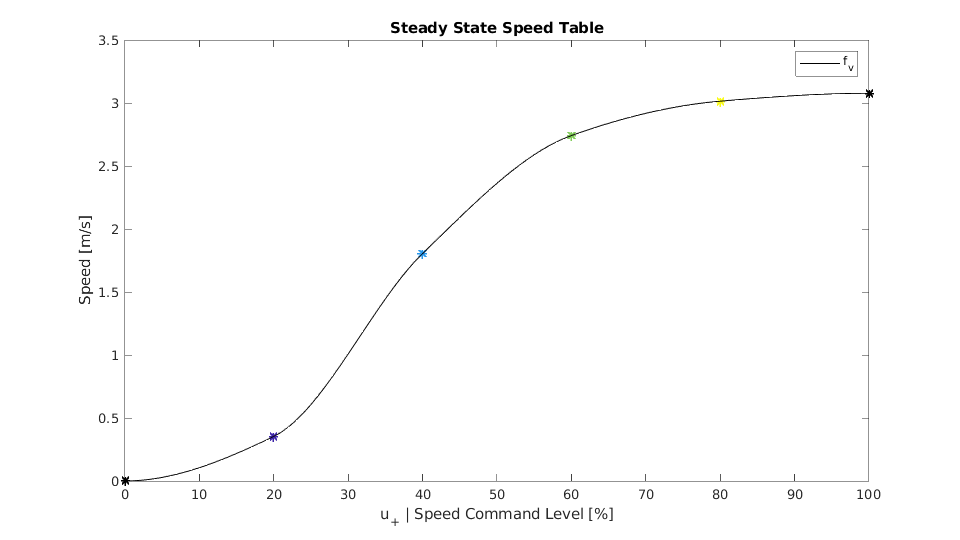


% Longitudinal FF Table: Result
fig2 = figure();
fig2.Position = [100 100 960 540];
box on
hold on
colorMap = parula(length(speedCommandLevelSteps));
for commandLevel = speedCommandLevelSteps
    for i = 1:length(speedLevelSteps{commandLevel == speedCommandLevelSteps})
        plot(commandLevel, speedLevelSteps{commandLevel == speedCommandLevelSteps}(i), ...
             '*', 'LineWidth', 1.5, 'color', colorMap(speedCommandLevelSteps == commandLevel,:));
    end
end
clear commandLevel colorMap i
plot(0, 0, ...
     'k*', 'LineWidth', 1.5);
plot(100, maxSpeed, ...
     'k*', 'LineWidth', 1.5);
FFspeedCommands_ = 0:100;
desideredSpeeds_ = interp1([0 speedCommandLevelSteps 100], ...
                          [0 speedMeanLevelSteps maxSpeed], ...
                          FFspeedCommands_, 'pchip');
desideredSpeeds = 0:speedStep:maxSpeed;
FFspeedCommands = interp1([0 speedMeanLevelSteps maxSpeed],...
                          [0 speedCommandLevelSteps 100], ...
                          desideredSpeeds, 'pchip');
plot(FFspeedCommands_, desideredSpeeds_, '-k');
title('Steady State Speed Table');
xlabel('u_+ | Speed Command Level [%]');
ylabel('Speed [m/s]');
legend({'','','','','','','f_v'})
xlim([0 100]);
orient(fig2,'landscape')
print(fig2,'2.1.SteadyLongitudinalFunction.pdf','-dpdf')


% Save FF Tables Results
writematrix([desideredSpeeds.' FFspeedCommands.'], 'FFspeed_USV.csv');

Results of interpolation have been saved in a csv file (FFspeed_USV.csv).

They could be used to fill a lookup table that maps a desired speed to a speed command resulting in a Feed Forward control action.


$$u_{v\;\textrm{FF}} =\;f_{v\;}^{-1} \left(v_{\textrm{des}} \right)$$


### 2.2 Longitudinal dynamic

In order to estimate a process model $G_v \left(s\right)$ with unity static gain, speed commands data are mapped in speed references through the non-linear $f_v \left(u_v \right)$.

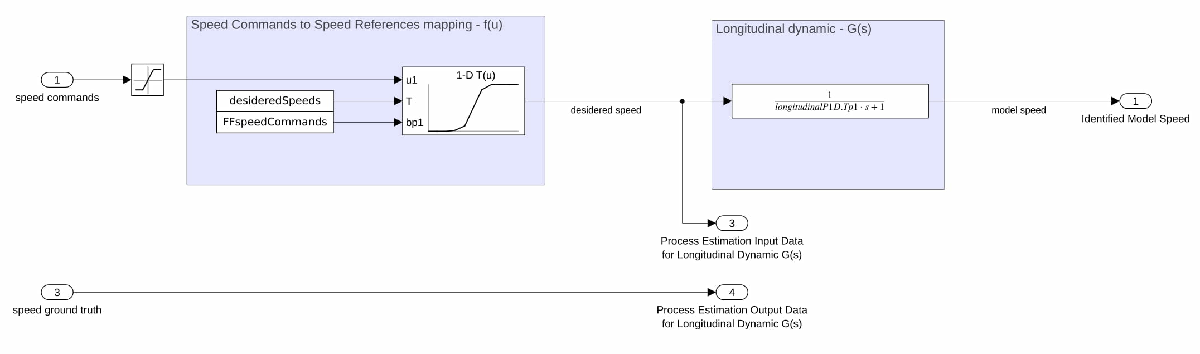

%% Longitudinal Dynamic
rangeIndex = USV.time>xlimLowLong & USV.time<xlimHighLong & ...
             squeeze(USV.speedCmd.Data).' > 30 & ...
             squeeze(USV.speedCmd.Data).' < 70;
idU = interp1(FFspeedCommands, desideredSpeeds, squeeze(USV.speedCmd.Data(rangeIndex)));
idY = squeeze(USV.longSpeed.Data(rangeIndex));
idData = iddata(idY, idU, SampleTime);
longitudinalP1D  = procest(idData,'P1D');

disp(['longitudinalP1D.Tp1 = ' num2str(longitudinalP1D.Tp1) 's']);

longitudinalP1D.Tp1 = 2.6298s


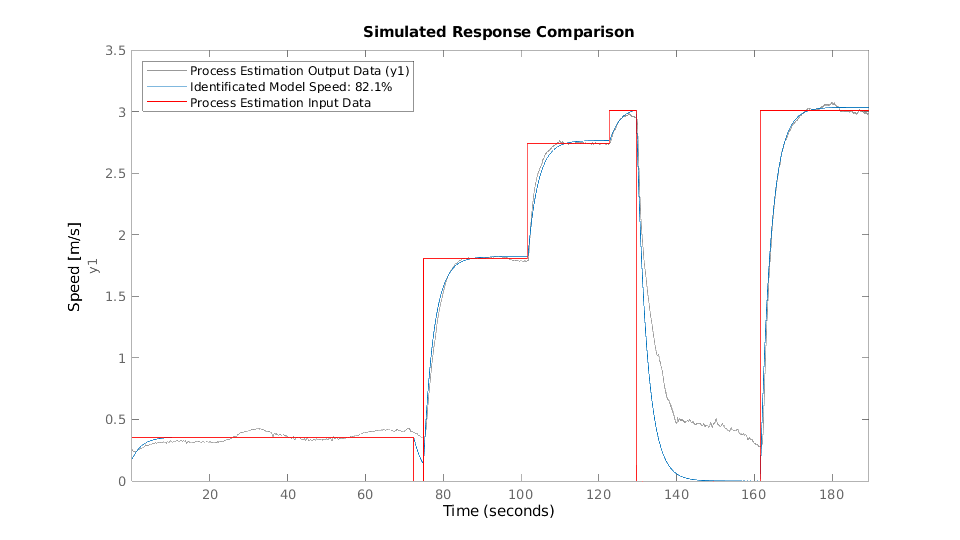


% Save Longitudinal Dynamic Parameters
writematrix(longitudinalP1D.Tp1, 'TAUspeed_USV.txt');

% fig6 = figure();
% fig6.Position = [100 100 960 540];
% box on
% compare(idData,longitudinalP1D);
% hold on
% plot((1:length(idU)).*SampleTime, idU, 'DisplayName','Speed Input');
% hold off
% ylabel('Speed [m/s]');
% clear rangeIndex idU idY idData
% legend('Location','northwest');
% orient(fig6,'landscape')
% print(fig6,'LongitudinalDynamicIdentification.pdf','-dpdf')

rangeIndex = USV.time>xlimLowLong & USV.time<xlimHighLong;
idU = interp1(FFspeedCommands, desideredSpeeds, squeeze(USV.speedCmd.Data(rangeIndex)),'linear','extrap');
idY = squeeze(USV.longSpeed.Data(rangeIndex));
idData = iddata(idY, idU, SampleTime);
fig7 = figure();
fig7.Position = [100 100 960 540];
box on
compare(idData,longitudinalP1D);
hold on
plot((1:length(idU)).*SampleTime, idU, 'r', 'DisplayName','Speed Input');
hold off
ylabel('Speed [m/s]');
clear rangeIndex idU idY idData
legend({'Process Estimation Output Data', 'Identificated Model Speed', 'Process Estimation Input Data'},'Location','northwest');
orient(fig7,'landscape')
print(fig7,'2.2.LongitudinalDynamic.pdf','-dpdf')

Identificated model output data fits the ground truth speed data according to a NRMSE of 82.1% (Normalized Root Mean Squared Error).

%% Clear
clear speedLevelSteps speedLevelStepsWeight
clear commandTol deltaTimeTol
clear legendFields FFspeedCommands_ desideredSpeeds_
clear speedMeanLevelSteps
clear xlimLowLong xlimHighLong
clear speedCommandDelay speedCommandLevelSteps speedStep maxSpeed

## 3. Open loop Test for Lateral Dynamic Identification

In the same way in order to identificate lateral dynamic, catamaran has been controlled with several constant yaw rate commands.

Every command level has been kept until vehicle has reached a steady state yaw rate value.

5 breakpoints has been evaluated avaraging along periods of time purged of transients.

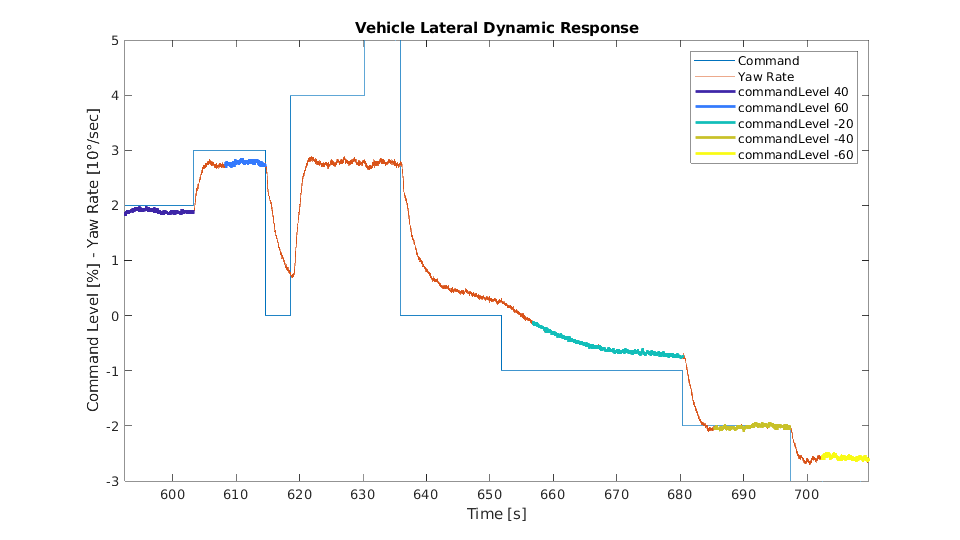


%% Lateral Feed Forward Table
yawRateCommandDelay = 5;                                % SET ME!!!
yawRateCommandLevelSteps = [40 60 -20 -40 -60];         % SET ME!!!
yawRateStep = 0.02;                                     % SET ME!!!
% maxYawRate = 0.50;                                      % Optional
% minYawRate = -0.52;                                     % Optional

if not(exist('maxYawRate', 'var'))
    maxYawRate = max(USV.yawRate.Data);
end
if not(exist('minYawRate', 'var'))
    minYawRate = min(USV.yawRate.Data);
end

commandTol = 0.5;
deltaTimeTol = SampleTime*1.05;

yawRateLevelSteps = cell(size(yawRateCommandLevelSteps));
yawRateLevelStepsWeight = cell(size(yawRateCommandLevelSteps));

fig3 = figure();
fig3.Position = [100 100 960 540];
box on
hold on
plot(USV.yawRateCmd/20);
plot(USV.yawRate*18/pi);
title('Vehicle Lateral Dynamic Response');
xlabel('Time [s]');
ylabel('Command Level [%] - Yaw Rate [10°/sec]');
legendFields = {'Command', 'Yaw Rate'};
xlimLowLat = inf;
xlimHighLat = -inf;
colorMap = parula(length(yawRateCommandLevelSteps));
for commandLevel = yawRateCommandLevelSteps
    usefulRange = abs(squeeze(USV.yawRateCmd.Data)-commandLevel) < commandTol & ...
                  abs(squeeze(USV.speedCmd.Data)) < commandTol;

    startUsefulPeriod = [diff(USV.time(usefulRange)).'; inf] < deltaTimeTol;
    startUsefulPeriod = startUsefulPeriod & [true; not(startUsefulPeriod(1:end-1))];
    startUsefulPeriodIndex = find(startUsefulPeriod);
    stopUsefulPeriodIndex = [startUsefulPeriodIndex(2:end)-1; length(startUsefulPeriod)];

    usefulYawRateRange = squeeze(USV.yawRate.Data(usefulRange));
    usefulTimeRange = USV.time(usefulRange);
    for i = 1:length(startUsefulPeriodIndex)
        usefulYawRatePeriod = usefulYawRateRange(startUsefulPeriodIndex(i):stopUsefulPeriodIndex(i));
        usefulTimePeriod = usefulTimeRange(startUsefulPeriodIndex(i):stopUsefulPeriodIndex(i));
        usefulYawRatePeriod = usefulYawRatePeriod(ceil(yawRateCommandDelay/SampleTime):end);
        usefulTimePeriod = usefulTimePeriod(ceil(yawRateCommandDelay/SampleTime):end);
        
        if not(isempty(usefulTimePeriod))       
            plot(usefulTimePeriod, usefulYawRatePeriod*18/pi,'LineWidth', 2, 'color', colorMap(yawRateCommandLevelSteps == commandLevel,:));

            yawRateLevelSteps{yawRateCommandLevelSteps == commandLevel} = [yawRateLevelSteps{yawRateCommandLevelSteps == commandLevel} ...
                                                                           mean(usefulYawRatePeriod)];
            yawRateLevelStepsWeight{yawRateCommandLevelSteps == commandLevel} = [yawRateLevelStepsWeight{yawRateCommandLevelSteps == commandLevel} ...
                                                                                 length(usefulTimePeriod)];
            legendFields{1+length(legendFields)} = [ 'commandLevel ' num2str(commandLevel)];
            xlimLowLat = min(xlimLowLat, usefulTimePeriod(1));
            xlimHighLat = max(xlimHighLat, usefulTimePeriod(end));
        end
        
    end
    
end
clear commandLevel colorMap usefulRange startUsefulPeriod startUsefulPeriodIndex stopUsefulPeriodIndex
clear usefulYawRateRange usefulTimeRange i usefulYawRatePeriod usefulTimePeriod

legend(legendFields);
xlim([xlimLowLat xlimHighLat]);
orient(fig3,'landscape')
print(fig3,'3.LateralIdentification.pdf','-dpdf')


yawRateMeanLevelSteps = zeros(size(yawRateCommandLevelSteps));
for commandLevel = yawRateCommandLevelSteps
    for i = 1:length(yawRateLevelSteps{commandLevel == yawRateCommandLevelSteps})
        yawRateMeanLevelSteps(commandLevel == yawRateCommandLevelSteps) = ...
            sum(yawRateLevelSteps{commandLevel == yawRateCommandLevelSteps}.*...
                yawRateLevelStepsWeight{commandLevel == yawRateCommandLevelSteps}./...
                sum(yawRateLevelStepsWeight{commandLevel == yawRateCommandLevelSteps}));
    end
end
for commandLevel = yawRateCommandLevelSteps
    if commandLevel ~= yawRateCommandLevelSteps(1)
        disp('______________________________________________')
    end
    disp(['Command Level: ' num2str(commandLevel,'%+i') '% | ' ...
          'Steady Yaw Rate: ' num2str(yawRateMeanLevelSteps(commandLevel == yawRateCommandLevelSteps)*180/pi) 'deg/sec']);
end

Command Level: +40% | Steady Yaw Rate: 18.9377deg/sec


______________________________________________


Command Level: +60% | Steady Yaw Rate: 27.7585deg/sec


______________________________________________


Command Level: -20% | Steady Yaw Rate: -5.4723deg/sec


______________________________________________


Command Level: -40% | Steady Yaw Rate: -20.1593deg/sec


______________________________________________


Command Level: -60% | Steady Yaw Rate: -25.7432deg/sec


clear commadLevel i

### 3.1 Lateral steady-state function

Non-linear function $f_v \left(u_v \right)$ can be obtained by interpolating the breakpoint values.

Missing of the +20% command has been fixed considering a symmetrical breakpoint. 

$f_{\omega \;} \left(0\right)=0$, $f_{\omega \;} \left(u_{\omega \;\;\textrm{MAX}} \right)={\omega \;}_{\textrm{MAX}}$ and $f_{\omega \;} \left(u_{\omega \;\;\textrm{MIN}} \right)={\omega \;}_{\textrm{MIN}}$ are assumed to be 3 more breakpoints.

if 1
% disp('______________________________________________');
disp(['Command Level: +20% | Steady Yaw Rate: ' num2str(-yawRateMeanLevelSteps(yawRateCommandLevelSteps == -20)*180/pi) 'deg/s']);
disp('______________________________________________');
disp('Command Level:  0%  | Steady Yaw Rate: 0deg/s');
disp('______________________________________________');
disp(['Command Level: +100%| Steady Yaw Rate: ' num2str(maxYawRate*180/pi) 'deg/s']);
disp('______________________________________________');
disp(['Command Level: -100%| Steady Yaw Rate: ' num2str(minYawRate*180/pi) 'deg/s']);
end

Command Level: +20% | Steady Yaw Rate: 5.4723deg/s


______________________________________________


Command Level:  0%  | Steady Yaw Rate: 0deg/s


______________________________________________


Command Level: +100%| Steady Yaw Rate: 28.8819deg/s


______________________________________________


Command Level: -100%| Steady Yaw Rate: -30.3617deg/s


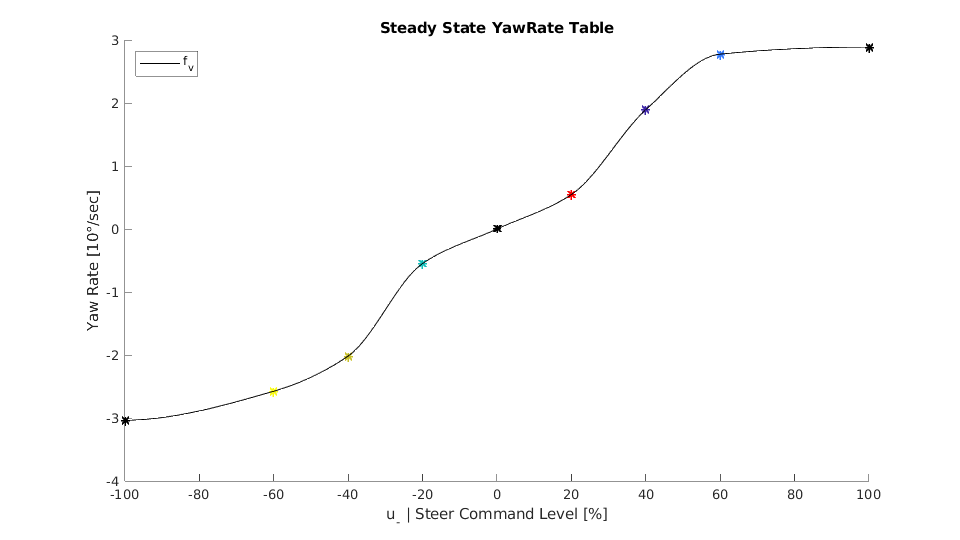


% Lateral FF Table: Fixed Result (fill symmetrical missing point)
yawRateCommandLevelStepsFixed = yawRateCommandLevelSteps;
yawRateMeanLevelStepsFixed = yawRateMeanLevelSteps;
fig5 = figure('Name', 'FeedForward Speed Gain Table Fixed');
fig5.Position = [100 100 960 540];
hold on
colorMap = parula(length(yawRateCommandLevelSteps));
for commandLevel = yawRateCommandLevelSteps
    plot(commandLevel, yawRateMeanLevelSteps(commandLevel == yawRateCommandLevelSteps)*18/pi, ...
         '*', 'LineWidth', 1.5, 'color', colorMap(yawRateCommandLevelSteps == commandLevel,:));
    if not(any(-commandLevel == yawRateCommandLevelSteps))
        yawRateCommandLevelStepsFixed = [yawRateCommandLevelStepsFixed ...
                                         -commandLevel];
        yawRateMeanLevelStepsFixed = [yawRateMeanLevelStepsFixed ...
                                      -yawRateMeanLevelSteps(commandLevel == yawRateCommandLevelSteps)];
        plot(-commandLevel, -yawRateMeanLevelSteps(commandLevel == yawRateCommandLevelSteps)*18/pi, ...
             'r*', 'LineWidth', 1.5);
    end
end
clear commandLevel
plot(0, 0, ...
     'k*', 'LineWidth', 1.5);
plot(-100, minYawRate*18/pi, ...
     'k*', 'LineWidth', 1.5);
plot(100, maxYawRate*18/pi, ...
     'k*', 'LineWidth', 1.5);
FFyawRateCommands_ = -100:100;
desideredYawRates_ = interp1([0 yawRateCommandLevelStepsFixed -100 100], ...
                             [0 yawRateMeanLevelStepsFixed minYawRate maxYawRate], ...
                             FFyawRateCommands_, 'pchip');
desideredYawRates = minYawRate:yawRateStep:maxYawRate;
FFyawRateCommands = interp1([0 yawRateMeanLevelStepsFixed minYawRate maxYawRate], ...
                            [0 yawRateCommandLevelStepsFixed -100 100], ...
                            desideredYawRates, 'pchip'); 
plot(FFyawRateCommands_, desideredYawRates_*18/pi, '-k');
clear commandLevel colorMap
title('Steady State YawRate Table');
xlabel('u_- | Steer Command Level [%]');
ylabel('Yaw Rate [10°/sec]');
legend({'','','','','','','','','','f_v'}, 'Location',"northwest")
xlim([-100 100]);
orient(fig5,'landscape')
print(fig5,'3.1.LateralSteadyFunction.pdf','-dpdf')


% Save FF Tables Results
writematrix([desideredYawRates.' FFyawRateCommands.'], 'FFyawRate_USV.csv');

Results of interpolation have been saved in a csv file (FFyawRate_USV.csv).

They could be used to fill a lookup table that maps a desired yaw rate to a yaw rate command resulting in a Feed Forward control action.


$$u_{\omega \;\;\textrm{FF}} =\;f_{\omega \;\;}^{-1} \left({\omega \;}_{\textrm{des}} \right)$$


### 3.2 Lateral dynamic

In order to estimate a process model $G_{\omega \;} \left(s\right)$ with unity static gain, yaw rate commands data are mapped in yaw rate references through the non-linear $f_{\omega \;} \left(u_{\omega \;} \right)$.

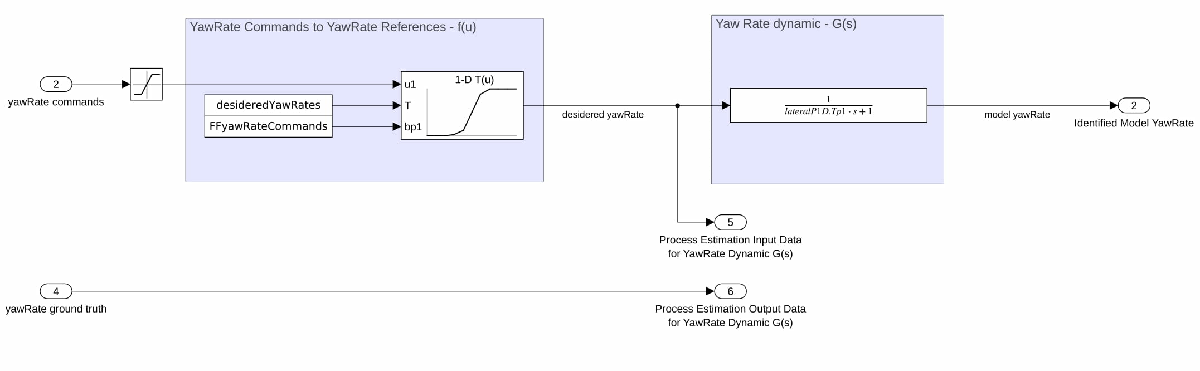

%% Lateral Dynamic
rangeIndexA = USV.time>xlimLowLat & USV.time<xlimHighLat & ...
              squeeze(USV.yawRateCmd.Data).' > 30 & squeeze(USV.yawRateCmd.Data).' < 70;
rangeIndexB = USV.time>xlimLowLat & USV.time<xlimHighLat & ...
              squeeze(USV.yawRateCmd.Data).' > -70 & squeeze(USV.yawRateCmd.Data).' < -30;
if sum(double(rangeIndexA))>sum(double(rangeIndexB))
    rangeIndex = rangeIndexA;
else
    rangeIndex = rangeIndexB;
end
clear rangeIndexA rangeIndexB
idU = interp1(FFyawRateCommands, desideredYawRates, squeeze(USV.yawRateCmd.Data(rangeIndex)), 'pchip');
idY = squeeze(USV.yawRate.Data(rangeIndex));
idData = iddata(idY, idU, SampleTime);
lateralP1D  = procest(idData,'P1D');

disp(['lateralP1D.Tp1 = ' num2str(lateralP1D.Tp1) 's']);

lateralP1D.Tp1 = 1.201s


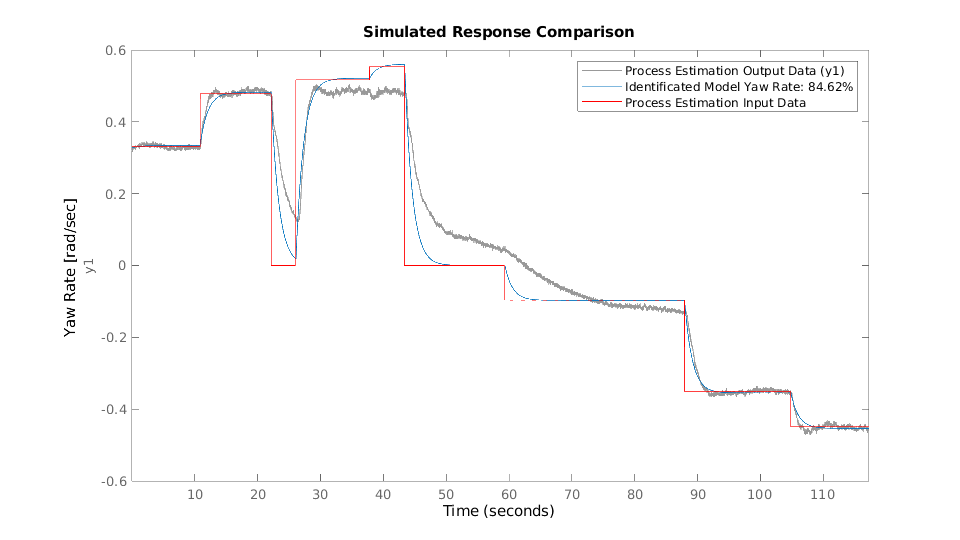


% Save Lateral Dynamic Parameters
writematrix(lateralP1D.Tp1, 'TAUyawRate_USV.txt');

% fig8 = figure();
% fig8.Position = [100 100 960 540];
% compare(idData,lateralP1D);
% hold on
% plot((1:length(idU)).*SampleTime, idU, 'DisplayName','Yaw Rate Input');
% hold off
% ylabel('Yaw Rate [rad/sec]');
% clear rangeIndex idU idY idData
% orient(fig8,'landscape')
% print(fig8,'LateralDynamicIdentification.pdf','-dpdf')

rangeIndex = USV.time>xlimLowLat & USV.time<xlimHighLat;
idU = interp1(FFyawRateCommands, desideredYawRates, squeeze(USV.yawRateCmd.Data(rangeIndex)),'linear','extrap');
idY = squeeze(USV.yawRate.Data(rangeIndex));
idData = iddata(idY, idU, SampleTime);
fig9 = figure();
fig9.Position = [100 100 960 540];
compare(idData,lateralP1D);
hold on
plot((1:length(idU)).*SampleTime, idU, 'r','DisplayName','Yaw Rate Input');
hold off
ylabel('Yaw Rate [rad/sec]');
clear rangeIndex idU idY idData
legend({'Process Estimation Output Data', 'Identificated Model Yaw Rate', 'Process Estimation Input Data'},'Location','northeast');
orient(fig9,'landscape')
print(fig9,'3.2.LateralDynamic.pdf','-dpdf')

Identificated model output data fits the ground truth speed data according to a NRMSE of 84.62% (Normalized Root Mean Squared Error).

%% Clear
clear yawRateLevelSteps yawRateLevelStepsWeight
clear commandTol deltaTimeTol
clear legendFields FFyawRateCommands_ desideredYawRates_
clear yawRateCommandLevelStepsFixed yawRateMeanLevelSteps yawRateMeanLevelStepsFixed
clear xlimLowLat xlimHighLat
clear yawRateCommandDelay yawRateCommandLevelSteps yawRateStep maxYawRate minYawRate